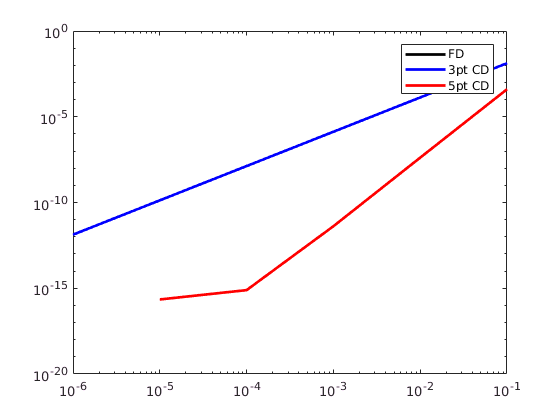

f = @(x) exp(-x.^2) * atan(x);
x = 0;
n = [10.^-1, 10.^-2, 10.^-3, 10.^-4, 10.^-5, 10.^-6];
nn = [1,2,3,4,5,6];
y1 = zeros(6,1);
y2 = zeros(6,1);
y3 = zeros(6,1);
for i = 1:1:length(n)
    y1(i) = (f(x + n(i)) - f(x)) / (n(i));
    y2(i) = ((f(x + n(i)) - f(x - n(i))) / (2*n(i)));
    y3(i) = ((-1 * f(x + 2*n(i)) + 8 * f(x + n(i)) - 8 * f(x - n(i)) + f(x - 2 * n(i))) / ( 12 * n(i)));
end
actual = @(x) (exp(-x.^2) * (1 - 2 * ((x.^3) + x) * atan(x)))/((x.^2) + 1);
error1 = abs(actual(0) - y1(:));
error2 = abs(actual(0) - y2(:));
error3 = abs(actual(0) - y3(:));
loglog(n,error1,'-k',n,error2,'-b',n,error3,'r','linewidth',2);
legend('FD','3pt CD','5pt CD');
hold off;




format long;
f = @(x) cos((pi*x.^2)/2);
n = [10, 10.^2, 10.^5];
exact = double(fresnelc(pi));
trap_arr = zeros(3,1);
simp_arr = zeros(3,1);
trap = zeros(3,1);
simp = zeros(3,1);
for i = 1:length(n)
    trap(i) = trap_int(f,0,pi,n(i));
    simp(i) = simp_int(f,0,pi,n(i));
    trap_arr(i) = abs(exact - trap(i));
    simp_arr(i) = abs(exact - simp(i));
end
trap

trap =    0.492232129253802
   0.523529681157319
   0.523698543561121


simp

simp =    0.073127934038341
   0.471261487614565
   0.523647276184936


exact

exact =    0.523698543726229


trap_arr

trap_arr =    0.031466414472426
   0.000168862568909
   0.000000000165108


simp_arr

simp_arr =    0.450570609687888
   0.052437056111664
   0.000051267541293


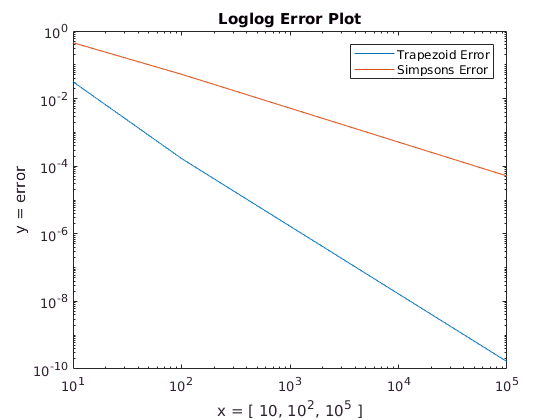

loglog(n,trap_arr,n,simp_arr);
title('Loglog Error Plot');
legend('Trapezoid Error','Simpsons Error');
xlabel('x = [ 10, 10^2, 10^5 ]');
ylabel('y = error');

As graph shows SImpon's rule decreases the error faster than Trapezoid rule.

function I = trap_int(f,a,b,n)
    h = (b-a)/(n-1);       % calculate h
    x = a+h:h:b-h;     % get the range of x from  a to b stepping with h
    % dx/2 * (f(x_0) + 2*f(x_k) + f(x_N))
    I = (h/2) * (f(a) + 2 * sum(f(x)) + f(b));
end
function I = simp_int(f,a,b,n)
    h = (b-a)/(n - 1);       % calculate h
    x_0 = f(a) + f(b); % calculate x_0
    x_1 = 0;
    x_2 = 0;
    for i = 1:n-1
        x = a+i*h;
        if mod(i,2) == 0
            x_2 = x_2 + f(x);
        else
            x_1 = x_1 + f(x);
        end
    end
    I = (h/3)*(x_0 + 4 * x_1 + 2 * x_2); 
end